Question 1.

Approximate the following integral

int[0,1]exp(x)

Using the composite midpoint rule, composite trapezoid rule, and composite Simpson's method. Each method should involve exactly n = 2^k + 1 integrand evaluations, k = 1 : 20. On the same plot, graph the absolute error as a function of n.

f = @(x)exp(x);
a = 0;
b = 1;
exact = exp(b) - exp(a);
x = linspace(1,20,20);
x = 2.^x + 1;
mpY = midpoint(f,a,b);
mpErr = abs(exact - mpY);
tzY = trapezoidal(f,a,b);
tzErr = abs(exact - tzY);
ssY = simpsons(f,a,b);
ssErr = abs(exact - ssY);
loglog(x, mpErr, "x", x, tzErr, "o", x, ssErr, "*");

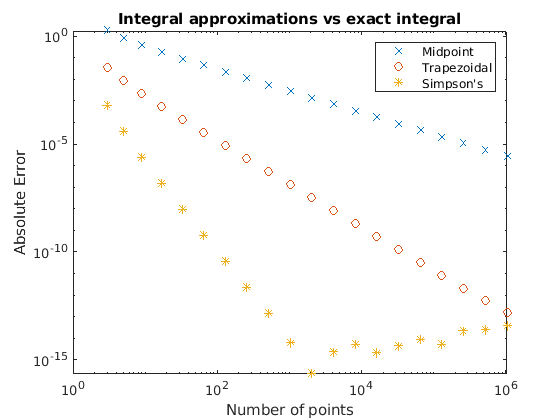

legend("Midpoint", "Trapezoidal", "Simpson's");
ylabel("Absolute Error");
xlabel("Number of points");
title("Integral approximations vs exact integral")

Looks like simpson's rule is best at all points but error tends to increase after about 10^3 points because compounding error.

Question 2.

y = integral(f,0,1);
MLIErr = abs(exact - y)

MLIErr = 4.4409e-16

Error is as low as lowest point on simpson's rule, if not lower.

Question 3.

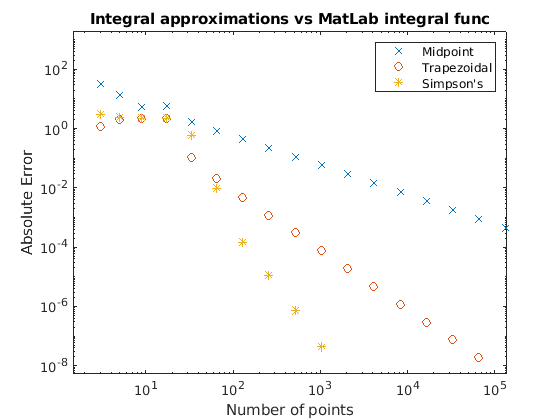

f = @(x) sqrt(1+cos(x).^2);
a = 0;
b = 48;
exact = integral(f,a,b);
mpY = midpoint(f,a,b);
mpErr = abs(exact - mpY);
tzY = trapezoidal(f,a,b);
tzErr = abs(exact - tzY);
ssY = simpsons(f,a,b);
ssErr = abs(exact - ssY);
loglog(x, mpErr, "x", x, tzErr, "o", x, ssErr, "*");
legend("Midpoint", "Trapezoidal", "Simpson's");
ylabel("Absolute Error");
xlabel("Number of points");
title("Integral approximations vs MatLab integral func")

function Y = midpoint(f, a, b)
    Y = zeros(1, 20);
    for k = 1:20
        X = linspace(a,b,2^k+1);
        deltaX = abs(X(1) - X(2));
        y = 0;
        for i = 1:numel(X)
            y = y + (deltaX*(f(X(i) + deltaX/2)));
        end
        Y(k) = y;
    end
    
end

function Y = trapezoidal(f, a, b)
    Y = zeros(1,20);
    for k = 1:20
        X = linspace(a,b,2^k+1);
        deltaX = abs(X(1) - X(2));
        y = 0;
        for i = 2:numel(X)
            y = y + (deltaX*(f(X(i-1)) + f(X(i))))/2;
        end
        Y(k) = y;
    end
end

function Y = simpsons(f, a, b)
    Y = zeros(1,20);
    for k = 1:20
        X = linspace(a,b,2^k+1);
        h = (b - a)/(numel(X) - 1);
        y = 0;
        for j = 1:((numel(X)-1)/2)
            y = y + f(X(2*j-1)) + 4*f(X(2*j)) + f(X(2*j+1));
        end
        y = (h / 3) * y;
        Y(k) = y;
    end
end